Gráficos para a análise da evolução dos erros para o cálculo de pi por diferentes métodos:

a) Desenvolvimento de arctan(x) pela série de Gregory

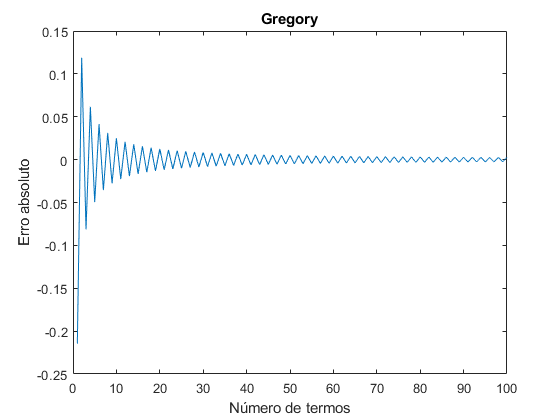


format long
a1(1)=1;
e1(1)=(pi/4-a1(1));
n1=100;
for k1=1:n1-1
    a1(k1+1) =a1(k1)+((-1)^(k1))/(2*k1+1);
    e1(k1+1)=(pi/4-a1(k1+1));
 t1=(1:k1+1);
end
plot (t1,e1)
title("Gregory")
xlabel("Número de termos") 
ylabel("Erro absoluto")

b) Aplicação da fórmula de Machin:

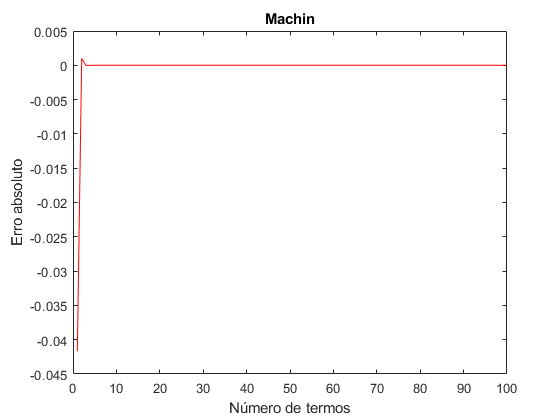


format long
%Arguments for atan()
x1 = 1/5;

x2 = 1/239;

%Totalnumberofdesiredapproximations

n2=100;

%atanapproximationsforxAandxBusingjustoneterm

a3(1) = x1;

b3(1) = x2;

%...andthecorrespondingapproximationforpi

p3(1) = 16*a3(1) - 4*b3(1);
e2(1) = (pi - p3(1));
%Improvetheapproximationbyincreasingthenumberoftermsused

for k2 = 1:n2-1
    
    a3(k2 + 1) = a3(k2) + (-1)^k2 * x1^(2*k2+1)/(2*k2+1);
    b3(k2 + 1) = b3(k2) + (-1)^k2 * x2^(2*k2+1)/(2*k2+1);
    p3(k2 + 1) = 16*a3(k2 + 1) - 4*b3(k2 + 1);
    e2(k2+1)=(pi-p3(k2+1));
    t2=(1:k2+1);
end

plot(t2,e2,')
title("Machin")
xlabel("Número de termos") 
ylabel("Erro absoluto")

c) Aplicação da fórmula de Hutton

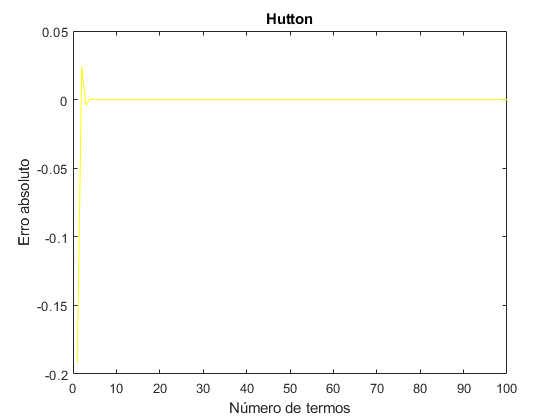


format long
%Arguments for atan()
x3 = 1/2;

x4 = 1/3;

%Totalnumberofdesiredapproximations

n3=100;

%atanapproximationsforxAandxBusingjustoneterm

a3(1) = x3;

b3(1) = x4;

%...andthecorrespondingapproximationforpi

p3(1) = 4*a3(1) + 4*b3(1);
e3(1) = (pi - p3(1));
%Improvetheapproximationbyincreasingthenumberoftermsused

for k3 = 1:n3-1
    
    a3(k3 + 1) = a3(k3) + (-1)^k3 * x3^(2*k3+1)/(2*k3+1);
    b3(k3 + 1) = b3(k3) + (-1)^k3 * x4^(2*k3+1)/(2*k3+1);
    p3(k3 + 1) = 4*a3(k3 + 1) + 4*b3(k3 + 1);
e3(k3+1)=(pi-p3(k3+1));
t3=(1:k3+1);
end

plot(t3,e3,'y')
title("Hutton")
xlabel("Número de termos") 
ylabel("Erro absoluto")

d) Aplicação da fórmula de Clausen

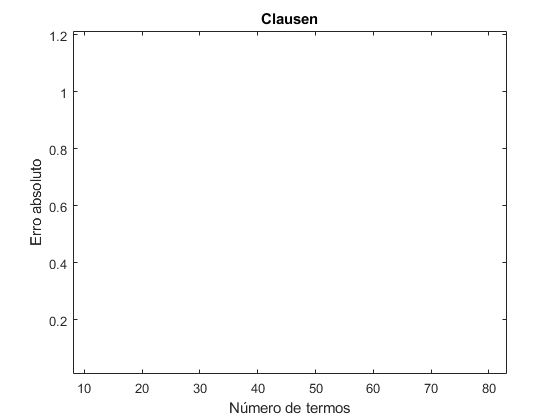


format long
%Arguments for atan()
x5 = 1/3;

x6 = 1/7;

%Totalnumberofdesiredapproximations

n4=100;

%atanapproximationsforxAandxBusingjustoneterm

a4(1) = x5;

b4(1) = x6;

%...andthecorrespondingapproximationforpi

p4(1) = 4*a4(1) + 4*b4(1);
e4(1) = (pi - p4(1));
%Improvetheapproximationbyincreasingthenumberoftermsused

for k4 = 1:n4-1
    %calculando atan(x3) por maclaurin
    a4(k4 + 1) = a4(k4) + (-1)^k4 * x5^(2*k4+1)/(2*k4+1); 
    
    %calculando atan(x4) por maclaurin
    b4(k4 + 1) = b4(k4) + (-1)^k4 * x6^(2*k4+1)/(2*k4+1); 
    
    p4(k4 + 1) = 8*a4(k4 + 1) + 4*b4(k4 + 1);
    e4(k4+1)=(pi-p4(k4+1));
    t4=(1:k4+1);
end

plot(t4,e4, 'm')
title("Clausen")
xlabel("Número de termos")
ylabel("Erro absoluto")

e) Aplicação da fórmula de Dase

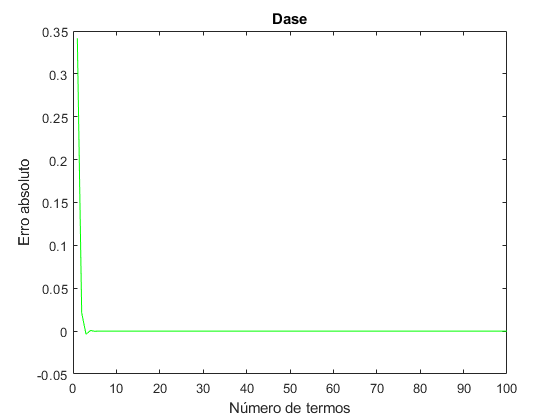


format long
%Arguments for atan()
x7 = 1/2;

x8 = 1/5;

x9=1/8;
%Totalnumberofdesiredapproximations

n5=100;

%atanapproximationsforxAandxBusingjustoneterm

a5(1) = x7;

b5(1) = x8;

c5(1)=x9;

%...andthecorrespondingapproximationforpi

p5(1) = 4*a5(1) + 4*b5(1);
e5(1) = (pi - p5(1));
%Improvetheapproximationbyincreasingthenumberoftermsused

for k5 = 1:n5-1
    
    a5(k5 + 1) = a5(k5) + (-1)^k5 * x7^(2*k5+1)/(2*k5+1);
    b5(k5 + 1) = b5(k5) + (-1)^k5 * x8^(2*k5+1)/(2*k5+1);
    c5(k5 + 1) = c5(k5) + (-1)^k5 * x9^(2*k5+1)/(2*k5+1);
    p5(k5 + 1) = 4*a5(k5 + 1) + 4*b5(k5 + 1)+ 4*c5(k5 + 1);
    e5(k5+1)=pi-p5(k5+1);
    t5=(1:k5+1);
end

plot(t5,e5,'g')
title("Dase")
xlabel("Número de termos") 
ylabel("Erro absoluto")

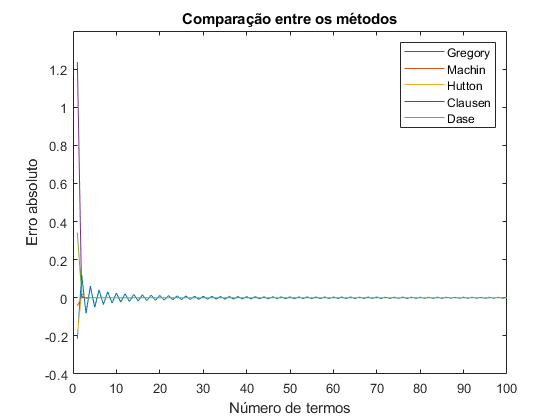

plot(t1,e1,t2,e2,t3,e3,t4,e4,t5,e5)
title("Comparação entre os métodos")
legend("Gregory","Machin", "Hutton","Clausen", "Dase")
xlabel("Número de termos") 
ylabel("Erro absoluto")